% Jep Brinkmann Thesis HMM example
clc; close all;
k = 4;
d = 30;
n = 5;

hmm_options.method = "random";
hmm_options.epsilon = 1/10;

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;
cpd_options.th_relerr = 1e-7;
cpd_options.epsilon = 1/10;

alpha = 0.9;
rho = 0.85;

T_seq = 1e6;

l = 30;
epsilon_range = logspace(-6, 0, l);

Nruns = 10;

UncoupledCost = zeros(l, Nruns);
CoupledCost = zeros(l, Nruns);

T_hats = cell(n,1);
O_hats = cell(n,1);

P3 = cell(n,1);



for j = 1:Nruns
    for i = progress(1:length(epsilon_range))
        hmm_options.epsilon = epsilon_range(i);
    
        [T, O, pi, k, d] = generateHMM(k, d, n, hmm_options);
        
        [seq, ~] = generate_multivariate_hmm_sequence(T, O, pi, T_seq);
        for kk = 1:n
            P3{kk} = ProbabilityTensorGenerate(seq(kk, :), 3, d);
        end

        T_hat = zeros(k,k);
        for ii = 1:n
            [A, B, C, ~, ~] = cpd_als_3d(P3{ii}, k, cpd_options);
            O_hat = Stochasticize(B);
            T_hats{ii} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));
        
            Pbest = PermutationFit(T, T_hats{ii}, true);
            T_hats{ii} = Pbest * T_hats{ii} * Pbest';
            T_hat = T_hat + (1/n) * T_hats{ii};
        
            O_hats{ii} = O_hat * Pbest';
        end
    
        UncoupledCost(i, j) = HMMError(T, O, T_hat, O_hats, false);  


        % Coupled CPD
        [T_hat, O_hats, ~, ~] = multivariate_coupled_cpd(P3, k, d, n, alpha, rho, cpd_options);
        pi_hat = findStationaryDistribution(T_hat')';
        [T_hat, O_hats, ~] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);
        
        CoupledCost(i, j) = HMMError(T, O, T_hat, O_hats, false);  
    end
end

Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN, Inf it/s]Processing:  000%  |                                        | 0/30it [00:00:00<Inf:NaN:NaN,


save("PerformanceTests/TransitionContrastPerformance", "UncoupledCost", "CoupledCost", "epsilon_range")

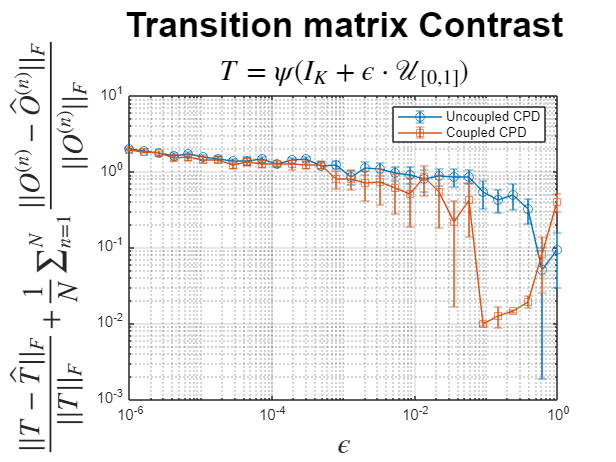

load("PerformanceTests/TransitionContrastPerformance")

UncoupledCostNO = (~isoutlier(UncoupledCost, 2)) .* UncoupledCost;
CoupledCostNO = (~isoutlier(CoupledCost, 2)) .* CoupledCost;

[UncoupledCostSTD, UncoupledCostMean] = std(UncoupledCost, 0, 2);
[CoupledCostSTD, CoupledCostMean] = std(CoupledCost, 0, 2);

UncoupledCostNO(UncoupledCostNO ==0) = NaN;
CoupledCostNO(CoupledCostNO == 0) = NaN;

% cmap = orderedcolors("gem");

figure()
errorbar(epsilon_range, UncoupledCostMean, UncoupledCostSTD/2, '-o'); hold on;
errorbar(epsilon_range, CoupledCostMean, CoupledCostSTD/2, '-s');

% scatter(epsilon_range', ((isoutlier(UncoupledCost, 2)) .* UncoupledCost), [], 'o'); hold on;
% scatter(epsilon_range', ((isoutlier(CoupledCost, 2)) .* CoupledCost), [], 's');

set(gca,'YScale','log', 'XScale', 'log');
% set(gca, 'XScale', 'log');
grid on; legend("Uncoupled CPD", "Coupled CPD", Location="northeast");
title("Transition matrix Contrast",'FontSize',24,'FontWeight','bold')
subtitle("$T = \psi(I_K + \epsilon \cdot \mathcal{U}_{[0, 1]})$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("$\epsilon$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')

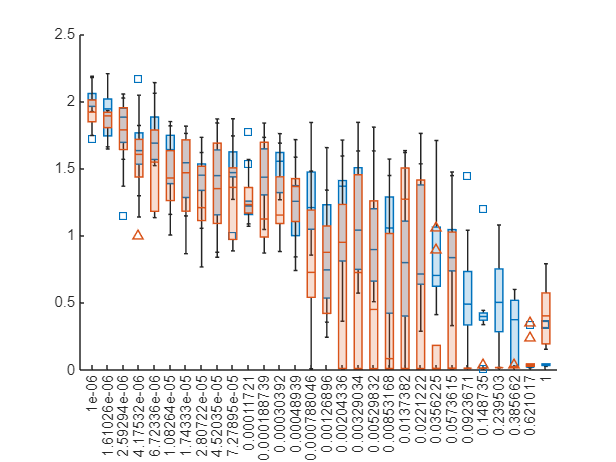

Error using xtickformat (line 34)
xtickformat is not supported for categorical rulers.



figure()
cmap = orderedcolors("gem");

boxchart(UncoupledCost', "MarkerStyle", 's'); hold on;
boxchart(CoupledCost', "MarkerStyle", '^'); hold on;

xticklabels(epsilon_range);


set(gca,'YScale','log');

grid on;
title("Transition matrix Contrast",'FontSize',24,'FontWeight','bold')
subtitle("$T = \psi(I_K + \epsilon \cdot \mathcal{U}_{[0, 1]})$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
ylabel("$\frac{||T - \hat{T}||_F}{||T||_F} + \frac{1}{N} \sum_{n=1}^N \frac{||O^{(n)} - \hat{O}^{(n)}||_F}{||O^{(n)}||_F}$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
xlabel("$\epsilon$", "Interpreter","latex",'FontSize',20,'FontWeight','bold')
legend("Uncoupled CPD", "Coupled CPD", Location="northeast");
hold off;

